##          Design Constants

% for Cable length
const.lambda1 = pi/3;
const.lambda2 = pi/2;

% For torque on CAM 
% Coordinates of fixed pulley wrt CAM axis of rotation
const.x2 = -36.04/1000;  
const.y2 = 61.25/1000;
const.x1 = -23.61/1000;
const.y1 = 18/1000;
const.pulley_rad = 5/1000; % radius
const.cam_lever = 55/1000; % length of CAM lever
const.init_cam_lever_ang = 59; %initial angle of CAM lever from horizontal

% For Beam deflection from CAM work 
const.spring_l = 45.5/1000; % effective length of beam spring
const.beam_stiffness = 8.09; % Nm/radian
const.init_deflection = (5/1000)/const.spring_l; % radian

% For CAM Profile
const.center_dist = 48.31/1000; % distance between virtual center of rotation for spring and CAM axis
const.base_radius = 14.5/1000; %minimum radius of the CAM

## **Converting Cable Displacement to CAM Angle**

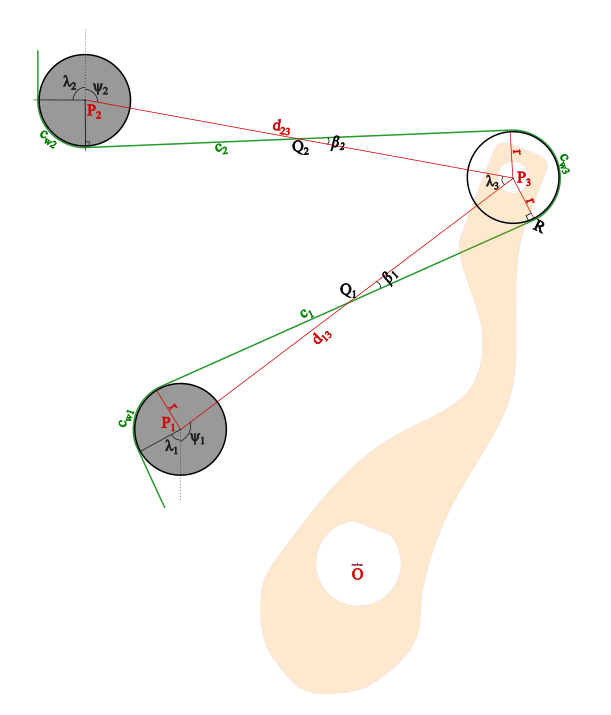

ang = linspace(0, 75*pi/180, 1000);
cable_len = zeros(length(ang),1);
for i=1:length(ang)
    cable_len(i) = get_cable_len(ang(i),const);
end

f = polyfit(rad2deg(ang), cable_len*1000,4)

f =     0.0000   -0.0004    0.0109   -1.6460  154.3158


M = [rad2deg(ang'),cable_len*1000]

M =          0  153.8148
    0.0751  153.7050
    0.1502  153.5952
    0.2252  153.4854
    0.3003  153.3755
    0.3754  153.2656
    0.4505  153.1556
    0.5255  153.0456
    0.6006  152.9356
    0.6757  152.8255


writematrix(M,"C:\Users\divg2\OneDrive\Desktop\cable_len_vs_cam_ang.txt")
f_inv = polyfit(cable_len*1000,rad2deg(ang),4)

f_inv =     0.0000   -0.0004    0.0613   -4.8285  200.1876


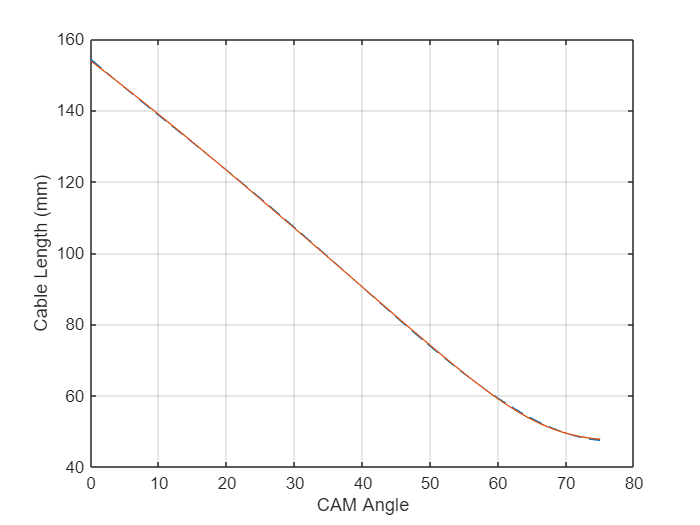

plot(rad2deg(ang),polyval(f,rad2deg(ang)),LineStyle="--")
hold on
plot(rad2deg(ang),cable_len*1000)

xlabel('CAM Angle')
ylabel('Cable Length (mm)')
grid on
hold off

rmse(cable_len'*1000,polyval(f,rad2deg(ang)))

ans = 0.1861

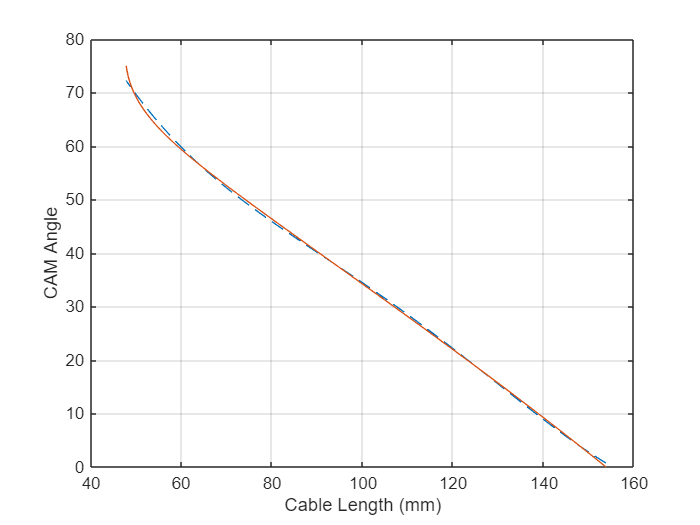

plot(cable_len*1000,polyval(f_inv,cable_len*1000),LineStyle="--")
hold on
plot(cable_len*1000, rad2deg(ang))
ylabel('CAM Angle')
xlabel('Cable Length (mm)')
grid on
hold off


displacement = (cable_len - min(cable_len))*1000;
displacement = -1*(displacement - max(displacement));


## Inputs to define CAM Profile - Desired Tension / Force at the cable as function of CAM rotation angle

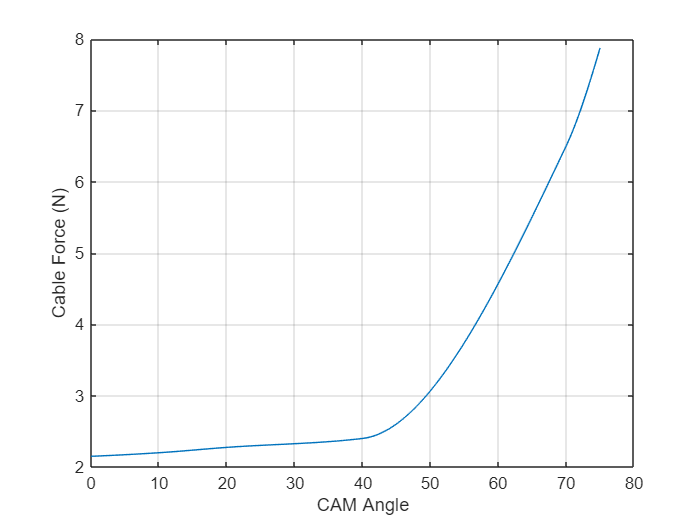

desired_force = [2.15 2.2 2.275 2.4 6.5 9.5 11];
enc_angle = [0 10 20 40 70 80 85]*pi/180;

% Interpolated values for desired torque curve
force = pchip(enc_angle, desired_force, ang);
% force = linspace(1,8,length(ang));
% Plotting Force vs Enc Angle Values
plot(rad2deg(ang),force);
xlabel('CAM Angle')
ylabel('Cable Force (N)')
grid on

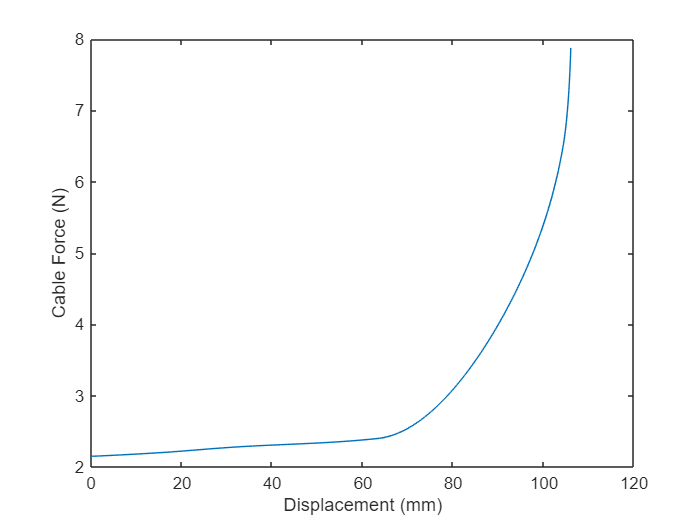


% ylim([0,9])
% xlim([0,75])
plot(displacement,force)
xlabel('Displacement (mm)')
ylabel('Cable Force (N)')

## Used for verification of cable angle wrt pulley and CAM lever through visualization, not needed for code

% alpha1 = [];
% alpha2 = [];
% for i=1:length(ang)
%     [alpha1(end+1), alpha2(end+1)]=get_tension_angles(ang(i),const);
% end
% find(alpha2==max(alpha2));
% ang(62); %angle at which it switches configuration for alpha2 (P3, P2 and CAM_origin in same line)
% plot(ang*180/pi,alpha1*180/pi)
% xlabel('Encoder Angle')
% ylabel('Alpha1 (Degree)')
% plot(ang*180/pi,alpha2*180/pi)
% xlabel('Encoder Angle')
% ylabel('Alpha2 (Degree)')

## **Getting torque at CAM axis and work done to rotate CAM**

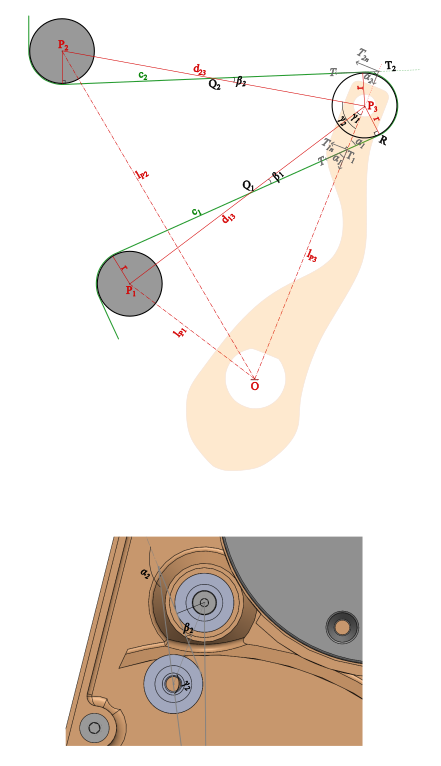

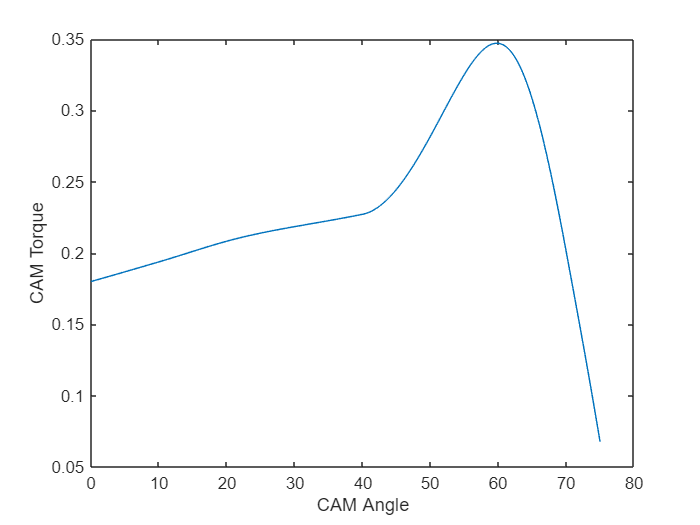

cam_torque = [];
alpha = [];
for i=1:length(ang)
    cam_torque(end+1)=get_torque(ang(i),force(i), const);
%     [alpha1,alpha2] = get_tension_angles(ang(i),const);
%     alpha = [alpha;alpha1,alpha2];
end
%% Here updating CAM_torque for testing purpose
% cam_torque = ones(length(ang),1)*0.5;
% cam_torque = linspace(0,1,length(ang));
plot(rad2deg(ang),cam_torque)
xlabel('CAM Angle')  
ylabel('CAM Torque')

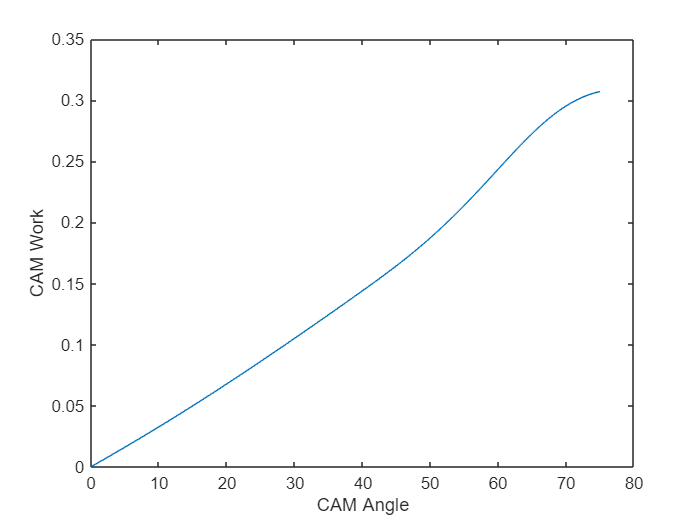

% grid on
dTheta = ang(2)-ang(1);
work = cumsum(cam_torque*dTheta);
plot(rad2deg(ang),work)
xlabel('CAM Angle')
ylabel('CAM Work')

% grid on

## **From CAM work to Beam Deflection and point load value**

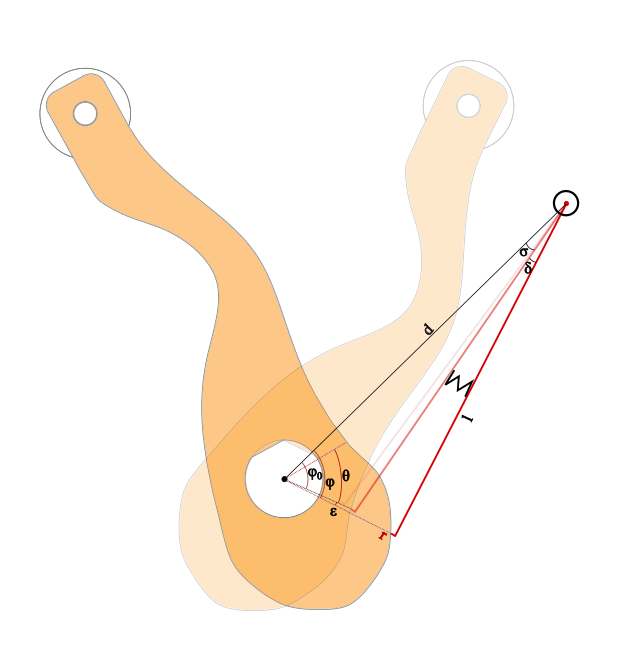

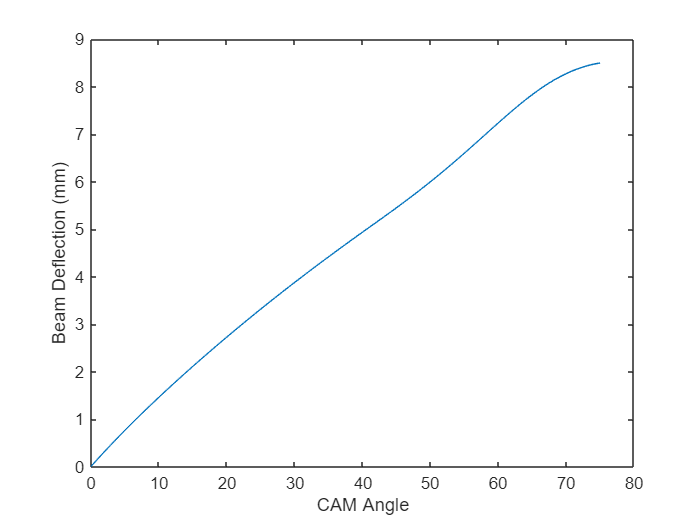

beam_defl = [];
beam_moment = [];
for i=1:length(ang)
    [beam_moment(end+1),beam_defl(end+1)] = get_beam_defl(work(i),const);
end 
plot(rad2deg(ang),beam_defl*const.spring_l*1000)
xlabel('CAM Angle')
ylabel('Beam Deflection (mm)')

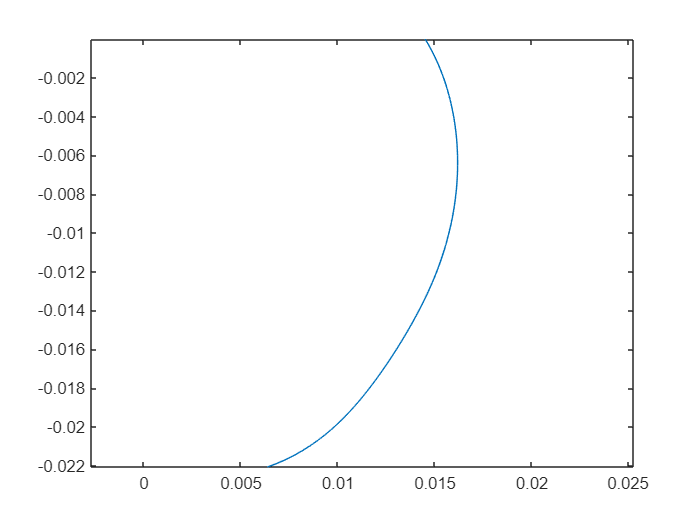

% grid on
x = [];
y = [];
r = [];
epsilon = [];
for i=1:length(ang)
    [radius_temp,epsilon_temp] = get_cam_polar_coords(beam_defl(i),const);
    r(end+1) = radius_temp;
    epsilon(end+1) = epsilon_temp;
    cam_ang_adjusted = -1*(ang(i)+epsilon_temp);
    [x(end+1),y(end+1)] = get_trace_point(radius_temp,cam_ang_adjusted);
end
plot(x,y)
% grid on
axis equal 

Extending the curve for full CAM

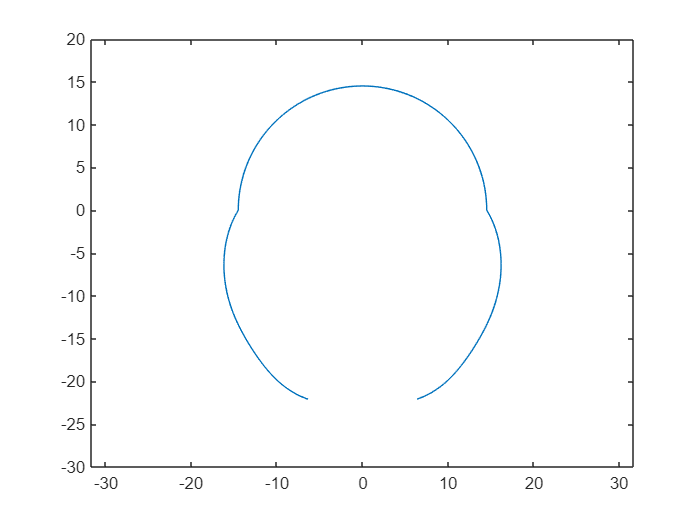

extended_ang = linspace(179*pi/180,1*pi/180,179);
extended_rad = r(1)*ones([179,1]);
extended_x_1 = [];
extended_y_1 = [];
for i=1:length(extended_ang)
    [extended_x_1(end+1), extended_y_1(end+1)] = get_trace_point(extended_rad(i),extended_ang(i));
end
extended_x_0 = [];
extended_y_0 = [];
extended_ang = epsilon+ang+pi;
extended_rad = r;
for i=1:length(extended_ang)
    [extended_x_0(end+1), extended_y_0(end+1)] = get_trace_point(extended_rad(i),extended_ang(i));
end
extended_x_0 = flip(extended_x_0);
extended_y_0 = flip(extended_y_0);

curve_x = [extended_x_0,extended_x_1,x];
curve_y = [extended_y_0,extended_y_1,y];

plot(curve_x*1000,curve_y*1000)
xlim([-25,25])
ylim([-30,20])
% grid on
axis equal 

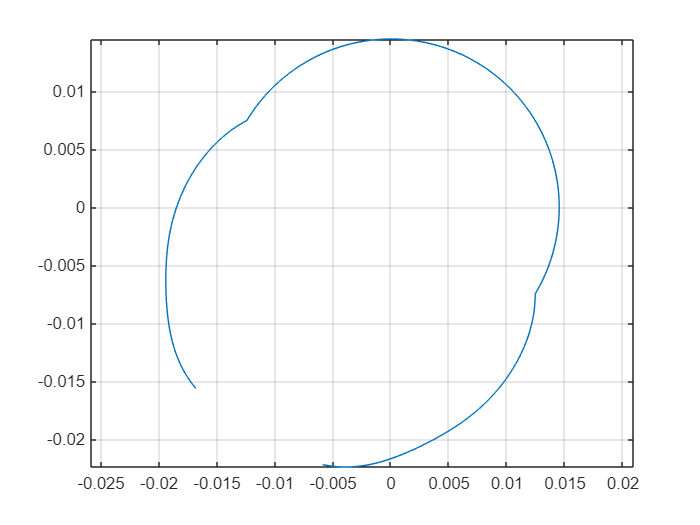

theta = -31;
R = [cosd(theta) -sind(theta);
    sind(theta) cosd(theta)];
vec = [curve_x;curve_y];
rot_vec = R*vec;
rot_x = rot_vec(1,:)';
rot_y = rot_vec(2,:)';
plot(rot_x,rot_y)
grid on
axis equal

export_trace(rot_x,rot_y)

% function cable_len = get_cable_len(cam_ang,const)
%     r = const.pulley_rad;
%     l_p3 = const.cam_lever;
%     x1 = const.x1;
%     y1 = const.y1;
%     x2 = const.x2;
%     y2 = const.y2;
%     theta = deg2rad(const.init_cam_lever_ang)+cam_ang;
%     x3 = l_p3 * cos(theta);
%     y3 = l_p3 * sin(theta);
% 
%     d_13 = norm([(x1-x3),(y1-y3)]);
%     d_23 = norm([(x2-x3),(y2-y3)]);
%     d_12 = norm([(x2-x1),(y2-y1)]);
%     
%     % cable lengths taut between pulleys
%     c1 = 2*sqrt((d_13/2)^2 - r^2);
%     c2 = 2*sqrt((d_23/2)^2 - r^2);
% 
%     %wrapped cable lengths
%     beta1 = acos(c1/d_13);
%     beta2 = acos(c2/d_23);
% 
%     % for P1
%     lambda1 = const.lambda1;
%     psi1 = pi/2 + acos((x3 - x1)/d_13);
%     wrapping_angle_p1 = 2*pi - lambda1 - (pi/2 - beta1) - psi1;
% 
%     % for P2
%     lambda2 = const.lambda2;
%     psi2 = pi/2 + acos((x3 - x2)/d_23);
%     wrapping_angle_p2 = 2*pi - lambda2 - (pi/2 - beta2) - psi2;
%     
%     %for P3
%     lambda3 = cosine_rule(d_13,d_23,d_12);
%     wrapping_angle_p3 = 2*pi - lambda3 - (pi/2 - beta1) - (pi/2 - beta2);
% 
%     cable_len = c1 + c2 + (wrapping_angle_p1 + wrapping_angle_p2 + wrapping_angle_p3)*r;
% end

function cable_len = get_cable_len(cam_ang,const) 
    % Haonan's modification
    r = const.pulley_rad;
    l_p3 = const.cam_lever;
    P1 = [const.x1; const.y1; 0];
    P2 = [const.x2; const.y2; 0];

    theta = deg2rad(const.init_cam_lever_ang)+cam_ang;
    P3 = [l_p3*cos(theta); l_p3*sin(theta); 0];

    d_13 = P1-P3;
    d_23 = P2-P3;

    % cable lengths taut between pulleys
    c1 = sqrt(norm(d_13)^2 - 4*r^2);
    c2 = sqrt(norm(d_23)^2 - 4*r^2);

    %wrapped cable lengths
    beta1 = asin(2*r/norm(d_13));
    beta2 = asin(2*r/norm(d_23));


    % for P1
    lambda1 = const.lambda1;
    psi1 = angle_between_two_vec([0;-1;0],-d_13);
    wrapping_angle_p1 = 2*pi - lambda1 - (pi/2 - beta1) - psi1;
    phi1 = -beta1+psi1;
    r1 = r*[cos(phi1);sin(phi1)];

    % for P2
    lambda2 = const.lambda2;
    psi2 = angle_between_two_vec(-d_23,[0;1;0]);
    wrapping_angle_p2 = 2*pi - lambda2 - (pi/2 - beta2) - psi2;
    phi2 = beta2-psi2;
    r2 = r*[cos(phi2);sin(phi2)];
    
    %for P3
    lambda3 = angle_between_two_vec(d_23,d_13);
    wrapping_angle_p3 = 2*pi - lambda3 - (pi/2 - beta1) - (pi/2 - beta2);

    cable_len = c1 + c2 + (wrapping_angle_p1 + wrapping_angle_p2 + wrapping_angle_p3)*r;
end

function [alpha1, alpha2] = get_tension_angles(cam_ang, const)
    r = const.pulley_rad;
    l_p3 = const.cam_lever;
    x1 = const.x1;
    y1 = const.y1;
    x2 = const.x2;
    y2 = const.y2;

    theta = deg2rad(const.init_cam_lever_ang)+cam_ang;
    x3 = l_p3 * cos(theta);
    y3 = l_p3 * sin(theta);
    p1 = [x1;y1];
    p2 = [x2;y2];
    p3 = [x3;y3];
    beta1 = asin(2*r/norm(p1-p3));
    beta2 = asin(2*r/norm(p2-p3));
    gamma1 = acos(-p3'*(p1-p3)/norm(p3)/norm(p1-p3));
    gamma2 = acos(p3'*(p2-p3)/norm(p3)/norm(p2-p3));
    alpha1 = beta1 + gamma1;
    alpha2 = beta2 + gamma2;

%     d_13 = norm([(x1-x3),(y1-y3)]);
%     d_23 = norm([(x2-x3),(y2-y3)]);
%     c1 = 2*sqrt((d_13/2)^2 - r^2);
%     c2 = 2*sqrt((d_23/2)^2 - r^2);
%     l_p1 = norm([x1,y1]);
%     l_p2 = norm([x2,y2]);
%     
%     gamma1 = cosine_rule(d_13,l_p3,l_p1);
%     gamma2 = cosine_rule(d_23,l_p3,l_p2);
%     beta1 = acos(c1/d_13);
%     beta2 = acos(c2/d_23);
%     alpha1 = gamma1+beta1;
%     if cam_ang<=1.0647 % It changes configuration here at the angle (shown in figure)
%         alpha2 = gamma2 -beta2;
%     else
%         alpha2 = pi-(gamma2 - (pi-beta2));  
%     end
end

function angle = cosine_rule(a,b,c)
    angle = acos((a^2 + b^2 - c^2) / (2*a*b));
end

function angle = angle_between_two_vec(a,b) % measured from vector a to vector b (ccw is positive)
    % Haonan's modification
    angle = acos(dot(a,b)/norm(a)/norm(b));
    c = cross(a,b);
    if c(3)<0
        angle = 2*pi - angle;
    end
end


% function cam_torque_calc = get_torque(enc_ang,force,const)
%     r = const.pulley_rad;
%     l_p3 = const.cam_lever;
%     [alpha1,alpha2] = get_tension_angles(enc_ang,const);
%     cam_torque_calc = force*l_p3*(sin(alpha1) + sin(alpha2));
% %     cam_torque_calc = force*sin(alpha1)*(l_p3 - r/sin(alpha1)) + force*sin(alpha2)*(l_p3 + r/sin(alpha2));
% end

function cam_torque_cal = get_torque(cam_ang,force,const)
    % Haonan's modification
    r = const.pulley_rad;
    l_p3 = const.cam_lever;
    P1 = [const.x1; const.y1; 0];
    P2 = [const.x2; const.y2; 0];
    theta = deg2rad(const.init_cam_lever_ang)+cam_ang;
    P3 = [l_p3*cos(theta); l_p3*sin(theta); 0];

    d_13 = P1-P3;
    d_23 = P2-P3;

    beta1 = asin(2*r/norm(d_13));
    beta2 = asin(2*r/norm(d_23));


    % for P1
%     lambda1 = const.lambda1;
    psi1 = angle_between_two_vec([0;-1;0],-d_13);
%     wrapping_angle_p1 = 2*pi - lambda1 - (pi/2 - beta1) - psi1;
    phi1 = -beta1+psi1;
    r1 = r*[cos(phi1);sin(phi1);0];

    % for P2
%     lambda2 = const.lambda2;
    psi2 = angle_between_two_vec(-d_23,[0;1;0]);
%     wrapping_angle_p2 = 2*pi - lambda2 - (pi/2 - beta2) - psi2;
    phi2 = beta2-psi2;
    r2 = r*[cos(phi2);sin(phi2);0];
    
    y1 = d_13 + 2*r1;
    tau1 = force*cross(P3-r1,y1/norm(y1));
    y2 = d_23 + 2*r2;
    tau2 = force*cross(P3-r2,y2/norm(y2));

    tau = tau1+tau2;
    cam_torque_cal = tau(3);
end

function [beam_moment,del_theta] = get_beam_defl(work,const)
    k = const.beam_stiffness;
    del_theta0 = const.init_deflection;
    del_theta = -del_theta0 + sqrt(del_theta0^2 + (2/k)*work);
    beam_moment = k*(del_theta+del_theta0);
end

function [r_theta,epsilon_theta] = get_cam_polar_coords(del_theta,const)
   l = const.spring_l;
   d = const.center_dist;
   r_theta0 = const.base_radius;

   phi_theta0 = cosine_rule(r_theta0,d,l);
   sigma = cosine_rule(d,l,r_theta0);

   r_theta = sqrt(l^2 + d^2 - (2*l*d*cos(sigma+del_theta)));
   
   phi_theta = cosine_rule(r_theta,d,l);
   epsilon_theta = phi_theta-phi_theta0;
end

function [x,y] = get_trace_point(r_theta,cam_ang_adjusted)
    x = r_theta*cos(cam_ang_adjusted);
    y = r_theta*sin(cam_ang_adjusted);
end

function cam_profile = export_trace(curve_x,curve_y)
    %% Export to Solidworks
    %This exports "cam_curve.txt" to your working folder.  To make a cam
    %profile with this curve, open up a cam in Solidworks, import curve through  
    %XYZ points, navigate to this .txt file, insert. Move this curve to the to
    %of your list of features.  Open up the first sketch, and "convert entity"
    %so you have this curve in your sketch. 
    curve_points = 1000*[curve_x, curve_y, 0*curve_x];
    writematrix(curve_points, 'C:\Users\divg2\OneDrive\Desktop\cam_curve.txt')
end
